# Final Assignment 5SMB0

saturated u = 2.2  @  r> | 2.3251 |

N = 100;
t = [0:0.1:400*pi]

t = 1.0e+03 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


r = t.*sin(0.09*t.*t) 

r = 1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0011    0.0012    0.0013    0.0015    0.0016    0.0018    0.0020    0.0022    0.0024    0.0025    0.0027    0.0029    0.0031    0.0033    0.0035    0.0037    0.0038    0.0040    0.0041    0.0042    0.0043    0.0043    0.0044    0.0043    0.0043    0.0042    0.0041


mode = 'open loop';
[u,y] = assignment_sys_14(r,mode)
plot(y)

Zooming into the function:

t = [0:0.1:40*pi];
r = t.*sin(0.08*t.*t);
mode = 'open loop';
[u,y] = assignment_sys_14(r,mode);
plot(y)
max_out = max(abs(y))

Rough estimation saturation y < |3.0|

max(abs(y))

ans = 2.9747

butterworth: 2nd order low-pass filter, cutt_off at 2.65 rad/s, stop band edge at 3.1 rad/s, => T_f = 3,14 rad/s 

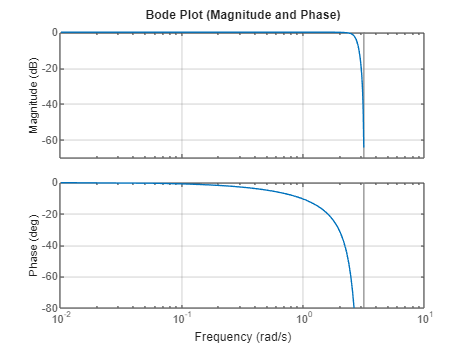

btt_num = [0.7157 1.4315 0.7157];
btt_den = [1 1.3490 0.5140];
figure;
F_butter = tf(btt_num, btt_den, 1.0);  %, -1
bode(F_butter);
ylim([-80 0]);
grid on;
title('Bode Plot (Magnitude and Phase)');

figure;
pzmap(F_butter)

Quite steep frequency roll over, visualization artifact caused by the bilinear transform of the filter. 

1.1 (3 points) The (partially) known parts of the system consist of F(q) and S. Determine

by an initial experiment the parameter M and explain what influence F(q) and

S will have on the identification of the unknown part H and G. This could be, e.g., on

the remaining steps of the system identification cycle, limitations on the obtained final

model, etc.

F(q) acts as a low pass filter, with a cut-off frequency of ~ 2.65 rad/s. The filter will have the effect of reducing the possible excitation range of the system, looking at the filter stats, excitation above stop-band edge frequency range will results in supression. Given the nyquist frequency of Pi rad/s, this cut-off frequency allows to filter high-frequency noise in the discrete frequency spectrum.

Function S is limiting the maximium input amplitude, and therefore input power into the system.

Therefore it's important for the system identification to limit input power/amplitude and excite only relevant frequencies, till nyquist frequency?

2.1 (4 points) We first want to get a rough idea of the frequency behavior of G0(q). To

this end, we want to perform a preliminary experiment and apply nonparametric system

identification using the collected data. The task is then to design an experiment of length

N = 1500. What type of reference shall be used? Give an expression of r(k) and motivate

your choice.

For performing model estimation with a non-parameric approach, an experiment should be designed that excite important frequences. To avoid specral leakage effects, a fundamentel frequency f_0 will be chosen with exicted harmonics on a logarithmic scale to equally distribute power throughout frequency decades. A uniformly distributed random phase is used to ensure a good crest factor

Max nyquist frequncy is pi rad/s => 1/2*T_s

N = 750; % number of points per period
fs = 1.0 %1; % sampling frequency in Hz

fs = 1

Ts = 1/fs;  % sampling interval in seconds
f0 = fs/N;  % the frequency resolution in Hz
fmin = 0.05%0.005; %fs/10;     % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax

fmin = 0.0500

fmax = 0.2%0.48; %fs/2 %0.35 %2*fs/5;   % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2

fmax = 0.2000

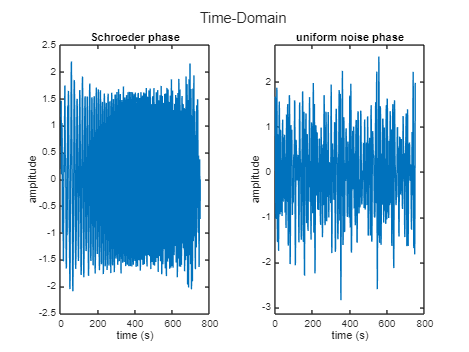

F = 30;    % maximum number of excited frequencies
t = (0:1:N-1)*Ts; % time vector in sec. we start at 0, so we need to stop at N*Ts-Ts to have a total of N samples
f = (0:1:N-1)*f0; % frequency vector in Hz




nmin = ceil(fmin/f0);  % the frequency bin of the lowest excited frequency
nmax = floor(fmax/f0); % the frequency bin of the highest excited frequency
bins = nmin:nmax;
binslog = round(logspace(log10(nmin),log10(nmax),F)); % logarithmically spaced frequency rounded to closest grid point
binslog = unique(binslog(:).'); % remove frequency bin values that appear multiple times in the vector
% due to this last operation, the total number of excited frequency can be
% lower than the previously defined F.
binslin = round(linspace(nmin, nmax, length(binslog)));

F = nmax-nmin+1;
% rescale amplitude bins to counteract filtering effect of the low-pass
w_bins = 2 * pi * f(bins+1); 
H_gain = freqresp(F_butter, w_bins);
gain_array = max(abs(squeeze(H_gain)), 1.0/10000.0);
% apply reverse gain to boost high-frequency content.
A = zeros(1,N/2-1); A(bins+1)=1 ./gain_array; % constant amplitude on the filtered excited frequency bins
% phi = zeros(1,N/2-1); phi(bins+1) = -(bins+1).*(bins).*pi/F; % Schroeder phase
phi = zeros(1,N/2-1); phi(bins+1) = -(bins-nmin+1).*(bins-nmin).*pi/F; % Schroeder phase
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));

usp = real(ifft(U))*N; %209.0  % 2.15 for 300 N     2.6 for 250N    3.0 for 500N
usp = 1.15*usp/std(usp); % scaled to have a standard deviation = 2
Usp = fft(usp);

A = zeros(1,N/2-1); A(binslog+1)=1; % constant amplitude on the excited frequency bins
%phi = zeros(1,N/2-1); phi(binslog+1) = 2*pi*rand(1,length(binslog));
%phi = zeros(1,N/2-1); phi(binslog+1) = -(binslog-nmin+1).*(binslog-nmin)*pi/F; % Schroeder phase
phi = zeros(1,N/2-1); phi(binslog+1) = 2*pi*rand(1,length(binslog)); % random phases, uniformly distributed between 0 and 2pi
U = zeros(1,N);
U(binslog+1) = A(binslog+1).*exp(1i*phi(binslog+1));
ulg = real(ifft(U))*N;
ulg = 0.7*ulg/std(ulg); % scaled to have max abs = 2
Ulg = fft(ulg);

A = zeros(1,N/2-1); A(binslin+1)=1; % constant amplitude on the excited frequency bins
phi = zeros(1,N/2-1); phi(binslin+1) = 2*pi*rand(1,length(binslin)); % random phases, uniformly distributed between 0 and 2pi
%phi = zeros(1,N/2-1); phi(binslin+1) = -(binslin-nmin+1).*(binslin-nmin).*pi/F;
U = zeros(1,N);
U(binslin+1) = A(binslin+1).*exp(1i*phi(binslin+1));
ueq = real(ifft(U))*N;
ueq = 0.9*ueq/std(ueq); % scaled to have max abs = 2
Ueq = fft(ueq);

yl = [min([ulg,ueq]), max([ulg,ueq])];
yl = 1.1*yl;

figure; tcl = tiledlayout(1,2); title(tcl,'Time-Domain')
nexttile; plot(t,usp); xlabel('time (s)'); ylabel('amplitude'); title('Schroeder phase');
nexttile; plot(t,ueq); xlabel('time (s)'); ylabel('amplitude'); title('uniform noise phase'); ylim(yl);

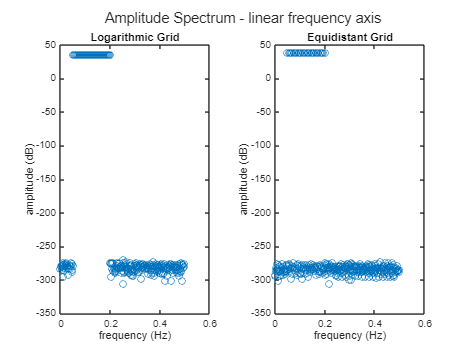

figure; tcl = tiledlayout(1,2); title(tcl,'Amplitude Spectrum - linear frequency axis')
nexttile; plot(f(1:end/2),db(Usp(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Logarithmic Grid'); yl = ylim;
nexttile; plot(f(1:end/2),db(Ueq(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Equidistant Grid'); ylim(yl);

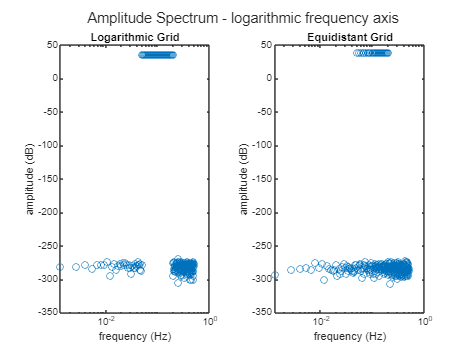

figure; tcl = tiledlayout(1,2); title(tcl,'Amplitude Spectrum - logarithmic frequency axis')
nexttile; semilogx(f(1:end/2),db(Usp(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Logarithmic Grid'); yl = ylim;
nexttile; semilogx(f(1:end/2),db(Ueq(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Equidistant Grid'); ylim(yl);

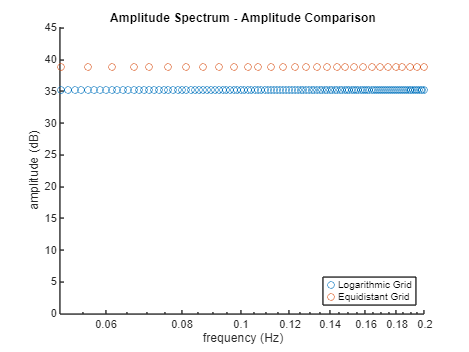

figure; hold on; title('Amplitude Spectrum - Amplitude Comparison')
semilogx(f(1:end/2),db(Usp(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)');  
semilogx(f(1:end/2),db(Ueq(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)');  
ylim([0 max(db(Usp(1:end/2)))+10]); set(gca, 'XScale', 'log'); legend('Logarithmic Grid','Equidistant Grid','Location','southeast')


Alg = max(abs(Usp)); disp(['Amplitude of excited frequencies - logarithmic grid: ' num2str(db(Alg)) ' dB'])

Amplitude of excited frequencies - logarithmic grid: 35.1713 dB


Aeq = max(abs(Ueq)); disp(['Amplitude of excited frequencies - equidistant grid: ' num2str(db(Aeq)) ' dB'])

Amplitude of excited frequencies - equidistant grid: 38.7988 dB


max(usp)

ans = 2.1908

Generate signal output with reference signal sure bud

mode = 'open loop';
N_per = 2;
repeat_usp = repmat(usp, 1, N_per);
[u,y] = assignment_sys_14(repeat_usp,mode);
max(u(20:1500))

ans = 2.1894

Alg = max(abs(Usp)); disp(['RMS Amplitude of filtered excitation: ' num2str(db(rms(abs(u(20:1500))))) ' dB'])

RMS Amplitude of filtered excitation: 1.2329 dB



% discard first period for transient system state and average over
% remaining periods
P_skip = 1;
y_matrix = reshape(y, N, N_per);
u_matrix = reshape(u, N, N_per);
y_steady = y_matrix(:, P_skip+1:end);
u_steady = u_matrix(:, P_skip+1:end);
U_filt = fft(u(N+1:2*N));
% average in time domain
u_avg = mean(u_steady, 2);
y_avg = mean(y_steady, 2); %y(1001:1500) %
U_avg = fft(u_avg)

U_avg =   -0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i


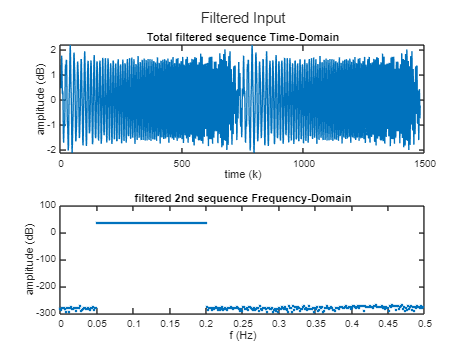

Y_avg = fft(y_avg);
% % average in frequency domain
% U_steady = fft(u_steady);
% Y_steady = fft(y_steady);
% U_avg = mean(U_steady, 2);
% Y_avg = mean(Y_steady, 2);


figure; tcl = tiledlayout(2,1); title(tcl,'Filtered Input');
nexttile;plot(u(20:end)); xlabel('time (k)'); ylabel('amplitude (dB)'); title('Total filtered sequence Time-Domain'); 
nexttile;plot(f(1:end/2),db(U_filt(1:end/2)),'.'); xlabel('f (Hz)'); ylabel('amplitude (dB)'); title('filtered 2nd sequence Frequency-Domain'); 

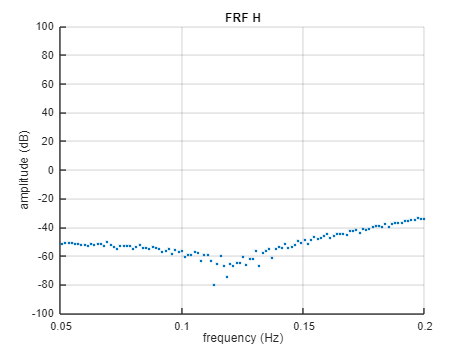

% figure;
% plot(y_avg); xlabel('time (k)'); ylabel('amplitude'); title('Averaged System output Time-Domain'); 

%FRF response, correct for filter dynamics by dividing over U
H = Y_avg ./ U_avg;

% Plot Magnitude
% figure; hold on; grid on;
% semilogy((db(abs(H(1:end/2))))); title('System Response (H)'); 
% figure; grid on;
% semilogy((db(phase(H(1:end/2))))); title('System Response (H)');

figure;hold on; grid on; xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('FRF H'); xlim([fmin, fmax]); %ylim([-80, 10]);
plot(f(1:end/2),db(H(1:end/2)),'.'); 

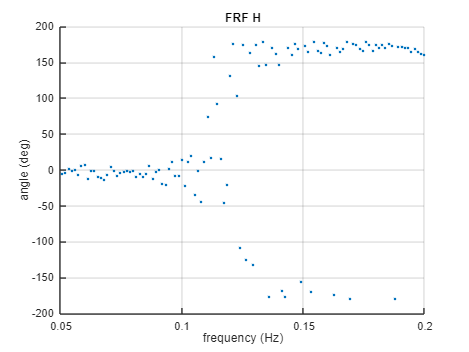

figure;hold on; grid on; xlabel('frequency (Hz)'); ylabel('angle (deg)'); title('FRF H'); xlim([fmin, fmax]); %ylim([-80, 10]);
plot(f(1:end/2), angle(H(1:end/2)) * (180/pi),'.'); %180*(angle(H(1:end/2)))/pi 



% Y = fft(y_avg);
% [u,y_e] = assignment_sys_14(ueq,mode);
% Y_e = fft(y_e);
% 
% figure;
% hold on; xscale('log'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Logarithmic grid FRF'); xlim([fmin, fmax]); ylim([-40, 40]);
% plot(f(1:end/2),db(Y(1:end/2)),'.'); 
% plot(f(1:end/2),db(Y_e(1:end/2)),'.');
% 
% figure; hold on; xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Equidistant grid FRF'); xlim([0.1, 0.5]); ylim([-40, 40]); 
% plot(f(1:end/2),db(Y(1:end/2)),'.'); 
% plot(f(1:end/2),db(Y_e(1:end/2)),'.'); 

parameterization? f

train_data = iddata(num2cell(y_steady(:, 1:end-0), 1), num2cell(u_steady(:, 1:end-0), 1), Ts);
val_data = iddata(num2cell(y_steady(:, end), 1), num2cell(u_steady(:, end), 1), Ts);
disp(train_data)

       iddata object: 4-D



size(train_data)

Data set with 1 output(s) and 1 input(s).
The set contains 5 experiments with [500 500 500 500 500] data points, respectively.


size(val_data)

Data set with 1 output(s) and 1 input(s).
The number of data points is 500.


opt = armaxOptions('Focus','simulation'); 
myarma = armax(train_data,[5 7 1 0], opt)


myarma =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                                        
  A(z) = 1 - 0.5885 z^-1 + 1.464 z^-2 - 1.457 z^-3 + 0.4765 z^-4 - 0.8122 z^-5                                   
                                                                                                                 
  B(z) = 0.006965 - 0.005997 z^-1 - 0.003792 z^-2 + 0.003784 z^-3 + 0.00583 z^-4 - 0.007174 z^-5 - 2.393e-05 z^-6
                                                                                                                 
  C(z) = 1 - 0.8246 z^-1                                                                                         
                                                                                                                 
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=7   nc=1   nk=0
   Number of free coefficients: 13
   Use "polydata", "getpvec", "getcov" for parameters and their

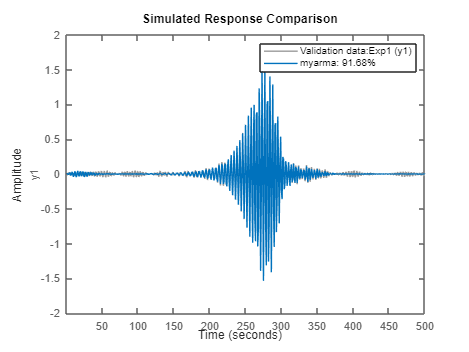


figure;compare(train_data, myarma, compareOptions('InitialCondition','z'));

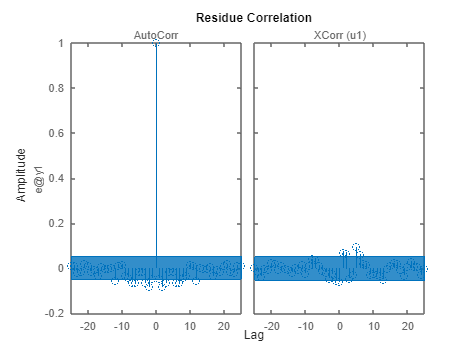

figure;resid(train_data, myarma);

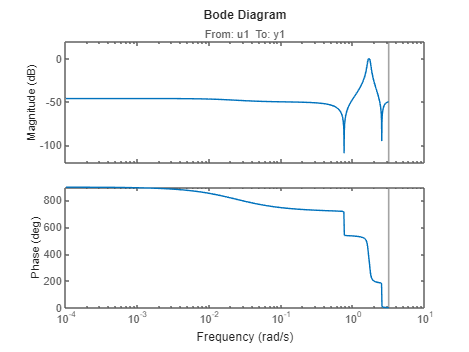

bode(myarma)

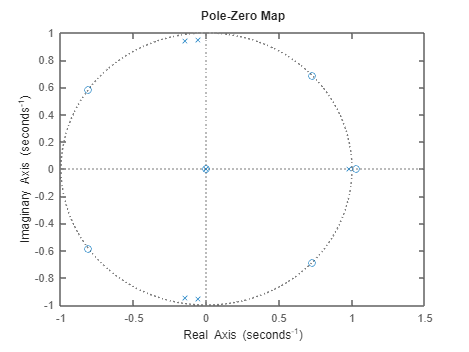

pzmap(myarma)

validate

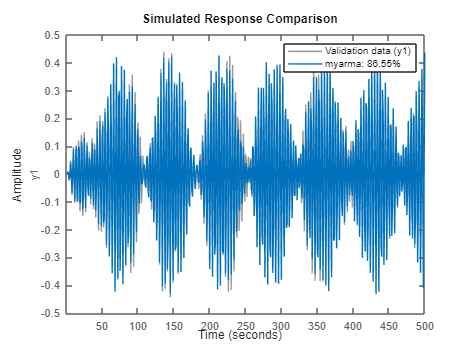

[uval,yval] = assignment_sys_14(ueq,mode);
val_data = iddata(yval, uval, Ts);
figure;compare(val_data, myarma, compareOptions('InitialCondition','z'));

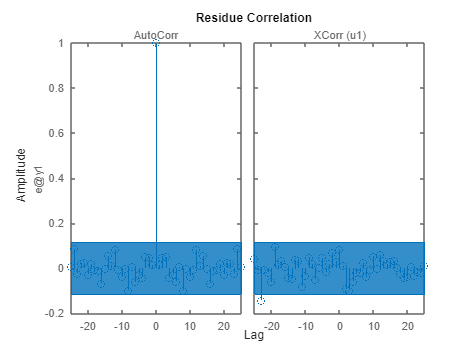

figure;resid(val_data, myarma);

emperical transfer function fit FRF : emprical transfer function estimation 

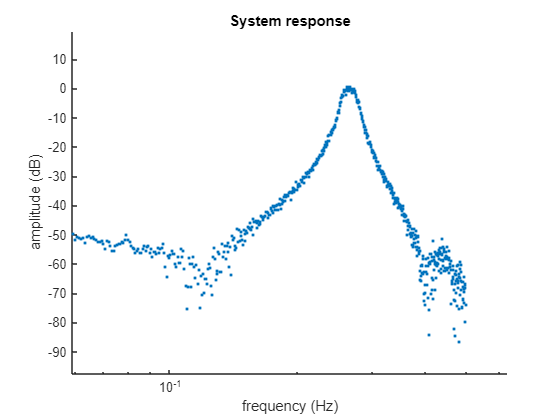

G_0 = Y ./ Usp';
figure; hold on; xscale('log'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('System response'); xlim([0.1, 0.5]); ylim([-40, 40]); 
plot(f(1:end/2),db(G_0(1:end/2)),'.'); 

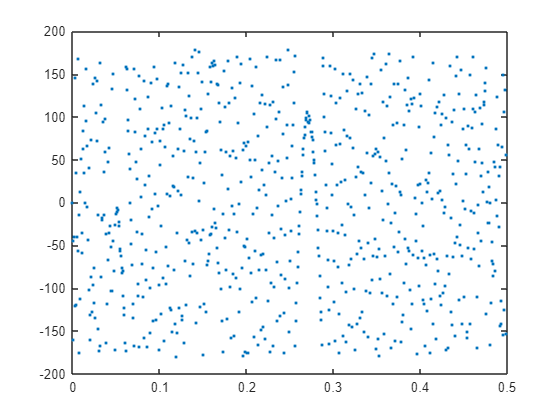

figure;
plot(f(1:end/2),((angle(G_0(1:end/2))) * (180/pi)), '.'); 

final FRF Aproach: Schroeder + fixed frequency portion , averaged over samples

G = complex(zeros(1, N))

G =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


for i = 1:1000
    [u,y] = assignment_sys_14(usp,mode);
    Y = fft(y);
    G(i, :) = Y ./ Usp';
    
end
G_average = 1.0/1000.0 * sum(G, 1)

G_average = 1.0e+11 *

   0.1945 + 0.0000i   0.1455 - 0.0633i      NaN +    NaNi  -0.0085 - 0.3943i   0.9127 - 0.2216i   0.0682 - 0.3334i   7.4288 - 5.5550i  -0.1053 - 0.0703i  -0.6463 + 0.1798i  -0.1728 - 0.9369i  -0.2380 + 0.2739i   0.1367 - 0.0776i  -0.0475 - 0.3450i   0.0123 - 0.0701i  -0.2622 + 0.0172i   0.1822 - 0.1795i   0.3359 - 0.4555i   0.2050 - 0.0043i  -0.2464 - 0.4147i   0.0937 + 0.1054i   0.7456 - 1.6976i   0.6889 + 0.0940i  -0.6686 - 0.7244i   0.2399 + 0.2588i   0.2643 - 0.4006i   0.2068 - 0.1372i  -0.4603 - 0.4929i   0.0171 + 0.1439i  -4.2761 - 1.5900i  -0.0929 + 0.4221i  -2.0085 - 0.4156i   0.7128 + 0.1906i   0.0992 - 1.7581i   0.4988 + 0.8180i  -0.4742 + 0.3176i   0.9852 + 0.4407i   0.1343 + 0.6732i  -0.5026 + 0.2835i  -0.3768 + 0.2126i   0.6028 + 0.8077i   0.9226 - 0.1015i  -1.1026 - 0.4597i  -0.9649 - 0.4928i  -0.4383 + 0.0887i  -0.2581 + 0.4935i  -0.1541 + 0.2058i   0.1465 + 0.2550i   0.1219 + 0.1338i  -0.0418 + 0.1383i  -0.1817 - 0.0329i


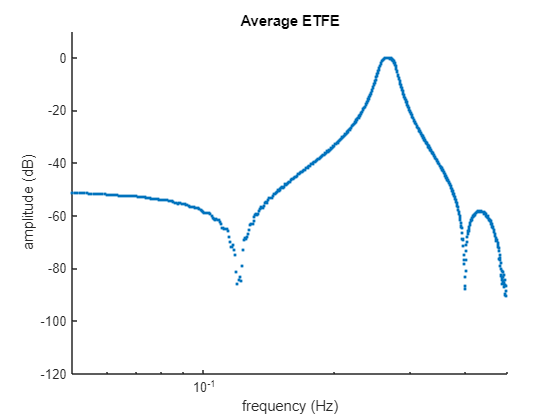

figure; hold on; xscale('log'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Average ETFE'); xlim([0.05, 0.5]); ylim([-120, 10]); 
plot(f(1:end/2),db(G_average(1:end/2)),'.'); 

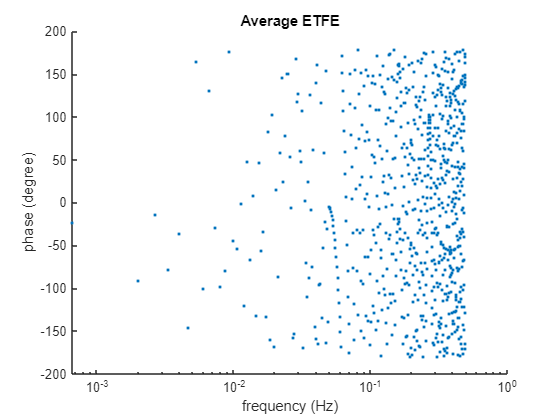


figure; hold on; xscale('log'); xlabel('frequency (Hz)'); ylabel('phase (degree)'); title('Average ETFE'); %xlim([0.05, 0.5]); ylim([-120, 10]); 
plot(f(1:end/2),((angle(G_average(1:end/2))) * (180/pi)), '.'); 

observations 2.2:

- Small resonance at ~0.27 Hz

- high-frequency charcterized by second peak at ~0.43 Hz

- Gain is mostly negative as illustrated by negative gain. 

G_average_noise_pwr = var(G, 1)

G_average_noise_pwr = 1.0e+27 *

    0.0156    0.0010       NaN    0.0016    0.0098    0.0043    3.9682    0.0018    0.0080    0.0089    0.0015    0.0020    0.0032    0.0014    0.0078    0.0026    0.0126    0.0034    0.0012    0.0012    0.0598    0.0081    0.0065    0.0012    0.0308    0.0012    0.0127    0.0302    0.1956    0.0124    0.0620    0.0066    0.0117    0.0050    0.0025    0.0040    0.0717    0.0029    0.0027    0.0024    0.2602    0.0125    0.0079    0.0088    0.0332    0.0048    0.0033    0.0008    0.0006    0.0008


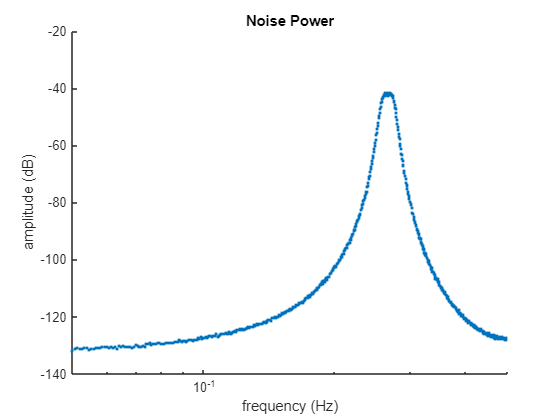

figure; hold on; xscale('log'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Noise Power'); xlim([0.05, 0.5]); ylim([-140, -20]); 
plot(f(1:end/2),db(G_average_noise_pwr(1:end/2)),'.'); 

Parametric approach: 

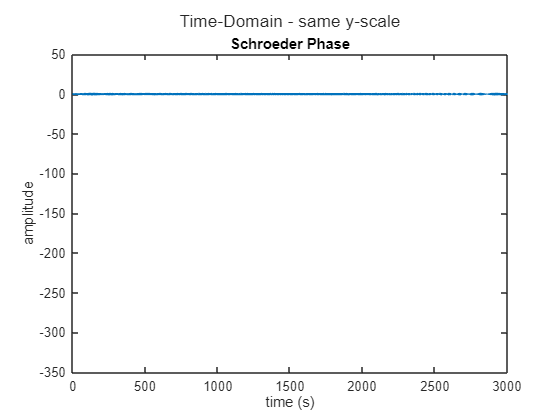

fs = 1;
N = 3000;
Ts = 1/fs;  % sampling interval in seconds
f0 = fs/N;  % the frequency resolution in Hz
fmin = 0.38;%0.01; % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax
fmax = 0.5;%0.5;   % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2

t = (0:1:N-1)*Ts; % time vector in sec. we start at 0, so we need to stop at N*Ts-Ts to have a total of N samples
f = (0:1:N-1)*f0; % frequency vector in Hz

nmin = ceil(fmin/f0);  % the frequency bin of the lowest excited frequency
nmax = floor(fmax/f0); % the frequency bin of the highest excited frequency
bins = nmin:nmax; % vector containing the excited frequency bins
F = nmax-nmin+1;
A = zeros(1,N/2-1); A(bins+1)=1; % constant amplitude on the excited frequency bins
% phi = zeros(1,N/2-1); phi(bins+1) = -(bins+1).*(bins).*pi/F; % Schroeder phase
phi = zeros(1,N/2-1); phi(bins+1) = -(bins-nmin+1).*(bins-nmin).*pi/F; % Schroeder phase
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
usp = real(ifft(U))*N;
usp = usp/std(usp); % scaled to have a standard deviation = 1
Usp = fft(usp);


figure; tcl = tiledlayout(1,1); title(tcl,'Time-Domain - same y-scale')
nexttile; plot(t,usp); xlabel('time (s)'); ylabel('amplitude'); title('Schroeder Phase'); ylim(yl);  

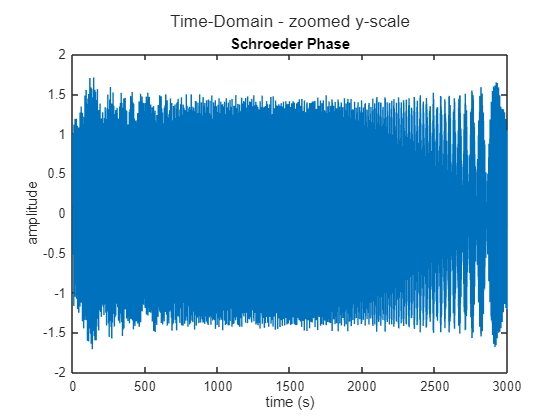


figure; tcl = tiledlayout(1,1); title(tcl,'Time-Domain - zoomed y-scale')
nexttile; plot(t,usp); xlabel('time (s)'); ylabel('amplitude'); title('Schroeder Phase'); 

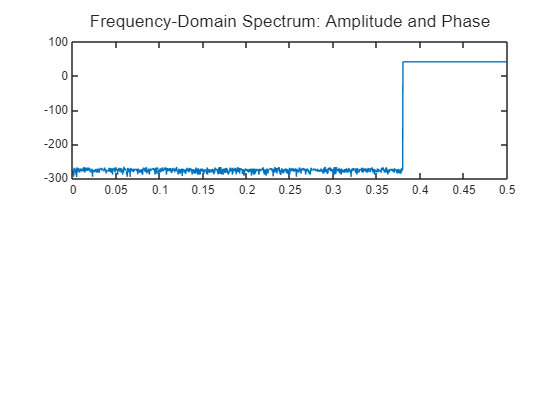


figure; tcl = tiledlayout(2,1); title(tcl,'Frequency-Domain Spectrum: Amplitude and Phase');
nexttile; plot(f(1:end/2),db(Usp(1:end/2)));

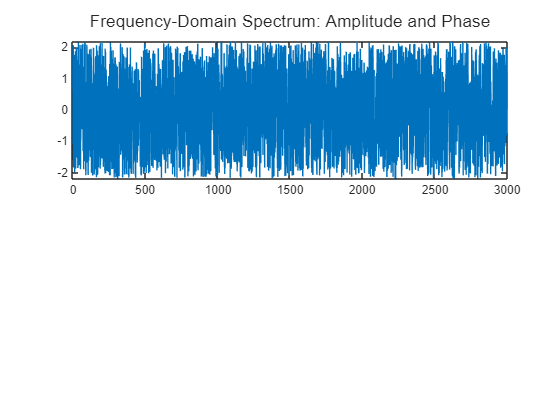

mode = 'open loop';
% Uniform white noise 
urand = rand(1,3000)-0.5;
urand = 1.26 * urand / std(urand);


plot(urand);

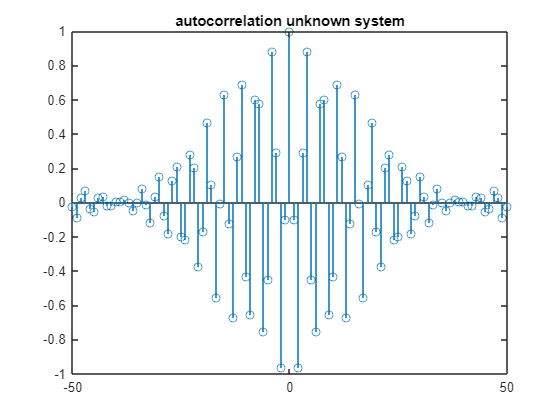

[u_est,y_est] = assignment_sys_14(usp,mode);
data_train = iddata(y_est, usp', Ts);
Y_est = fft(y_est);

[csys, lagsys] = xcorr(y_est,'normalized');
figure; stem(lagsys, csys); title("autocorrelation unknown system"); xlim([-50, 50]);

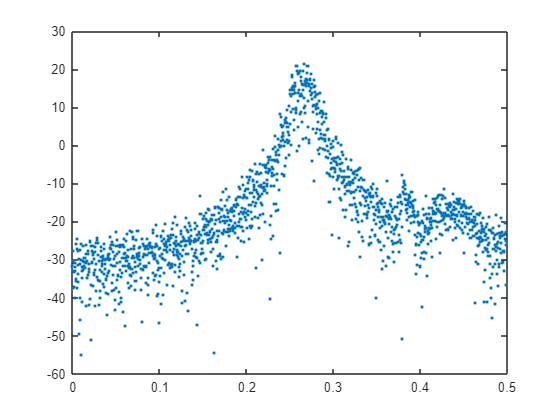




figure; xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Equidistant grid FRF'); ylim([-60, 40]); %xlim([0.1, 0.5]); 
plot(f(1:end/2),db(Y_est(1:end/2)),'.'); 

max(urand)

ans = 2.1719



opt = armaxOptions('Focus','simulation'); 

ute =    -0.2862    2.1320    0.6579   -1.4592   -0.1364   -2.1483   -0.2854    0.3313    1.3103    1.8446   -0.2496   -0.7603    2.1043   -0.9041    1.0229    0.8464    2.0455    1.0449   -1.1077    1.0667   -0.2601   -0.3641    0.7732   -1.8640    0.2973    1.1613   -0.4647    1.6114   -1.5458   -0.1621   -0.0057    1.6006   -0.6220   -0.2962   -0.1235    1.5427    1.7348    0.4387   -0.2249   -0.3604   -0.8611    1.6008   -1.3210   -1.5144   -1.0345   -1.6143   -1.6340   -0.4348   -2.1388   -0.2750


yte =    -0.0001
    0.0078
    0.0123
   -0.0335
   -0.0228
    0.0646
    0.0171
   -0.0956
    0.0073
    0.1191


myarma = armax(usp', y_est,[6 4 2 0], opt)
compare(data_train, myarma, compareOptions('InitialCondition','z'))


myarma =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                  
  A(z) = 1 + 0.6746 z^-1 + 2.342 z^-2 + 1.029 z^-3 + 1.636 z^-4 + 0.3705 z^-5 + 0.3179 z^-6
                                                                                           
  B(z) = 0.004171 + 0.004107 z^-1 - 0.003692 z^-2 - 0.003284 z^-3                          
                                                                                           
  C(z) = 1 + 0.6957 z^-1 + 0.777 z^-2                                                      
                                                                                           
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=4   nc=2   nk=0
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                       
Estimated using ARMAX on time domain data.    
Fit to estimation data: 88% (simulation foc

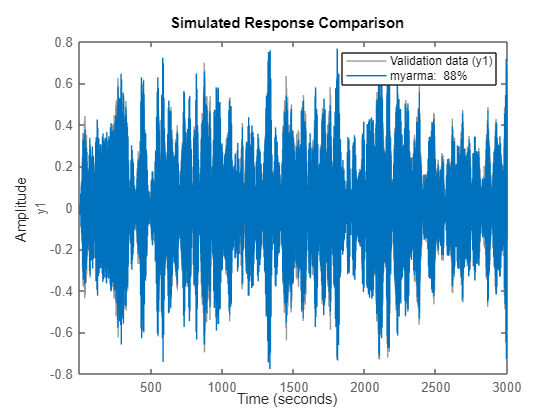

% data_test = iddata(y_est, usp', Ts); 


% sys = armax(data_train,[3 4 3 1])
% opt = compareOptions('InitialCondition','estimate'); 
% [y,Fit] = compare(data_train,sys,opt)

urand2 = rand(1,3000)-0.5;
urand2 = 1.26 * urand2 / std(urand2)
y_test = assignment_sys_14(urand2,mode);  % lsim(arma, urand');

urand2 =    -1.1564   -0.0210   -1.0725   -1.8501    0.6135   -0.1928    0.3742   -0.7066    0.7457   -1.7765   -1.4957   -0.5178   -1.9234   -0.9120   -1.7596    1.2422    1.4543    1.7799   -0.0145    0.0483    0.3692    0.3185    2.1397   -1.0604    2.1335    1.4867    1.0842    1.0254    0.1756    1.6240   -0.2589   -2.1588    0.9656    0.6610   -1.7785    1.9757    1.8738   -0.2310   -1.7234   -1.2618    1.3333    1.6566   -1.7349   -1.3892    1.3247    1.1362    1.7437    0.7453   -0.6754    0.1518


data_test = iddata(y_test, urand2', Ts);
arma_y = lsim(myarma, urand2');
arma_Y = fft(arma_y);
bode(myarma);
% figure; hold on;
% plot(y_est);
% plot(arma_y)
% 
% 
% compare(data_test, arma);
resid(data_test, myarma);

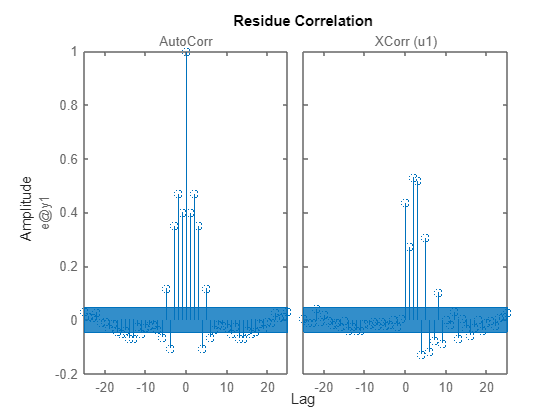

[c, lag] = xcorr(y_test,'normalized');

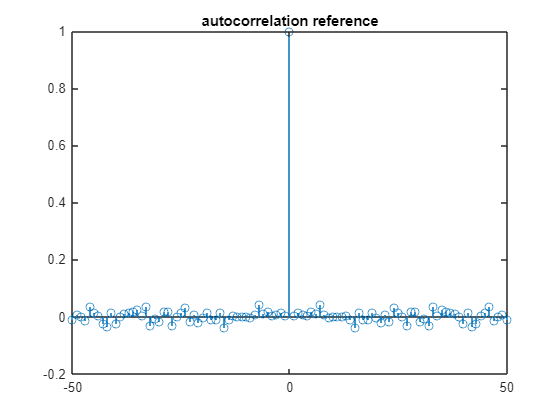

[carma, lagarma] = xcorr(arma_y,'normalized');
[cref, lagref] = xcorr(urand2','normalized');
[carmref, lagarmref] = xcorr(urand2', arma_y,'normalized');
figure; stem(lagref, cref); title("autocorrelation reference"); xlim([-50, 50]);
figure; stem(lagarma, carma); title("autocorrelation arma"); xlim([-50, 50]);
figure; stem(lagarmref, carmref); title("correlation reference - arma"); xlim([-100, 100]);

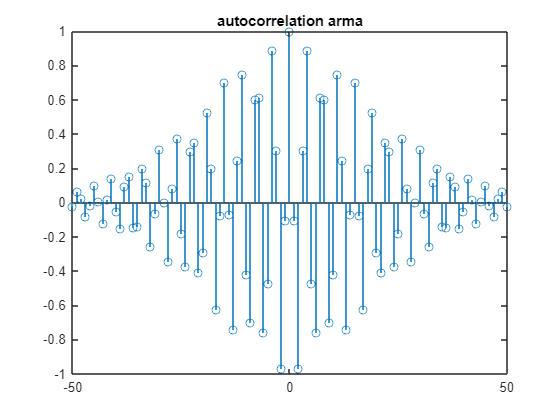

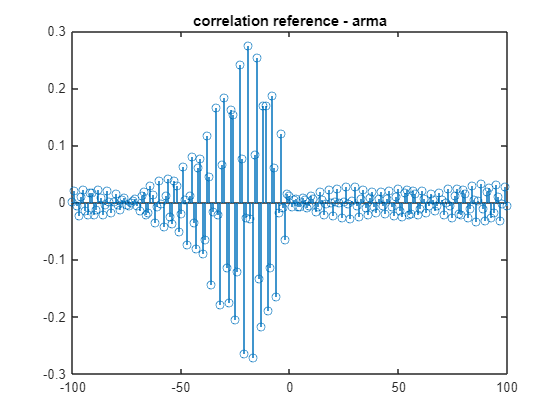

s

na = 1:12; nb = 3:8; nc = 1:5; nk = 0:2;

Unrecognized function or variable 's'.

best_fit = inf;
best_order = [];

for i = na
    for j = nb
        for k = nc
            for l = nk
                sys = armax(ute', yte,[i j k l], opt);
                if sys.Report.Fit.FPE < best_fit
                    best_fit = sys.Report.Fit.FPE;
                    best_order = [i j k l];
                end
            end
        end
    end
end


y_arma = lsim(arma, usp');

Unrecognized function or variable 'arma'.

var_arma = var(y_arma, 1)
VAR_arma = fft(var_arma)
Y_arma = fft(y_arma); 
figure; hold on; xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('arma response'); %xlim([0.05, 0.5]); ylim([-120, 10]); 
plot(f(1:end/2),db(Y_arma(1:end/2)),'.'); 
figure; hold on; xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('arma variance'); %xlim([0.05, 0.5]); ylim([-120, 10]); 
plot(f(1:end/2),db(VAR_arma(1:end/2)),'.'); 

% Uniform zero-mean white noise 
tst = rand(1,3000)-0.5;
tst = 1.26 * tst / std(tst)

tst =    -0.8218   -0.5266   -2.0832    0.4542    1.5732   -1.9878    1.9555   -1.5850    0.9831    2.0195   -0.0172   -1.1255    0.1431   -0.4244   -0.0469    1.1806   -0.6008    1.1638    0.9979    1.9370   -1.9537    1.8392    1.6378   -1.1310   -0.0887    0.1315    1.0691   -1.0714   -0.8486    0.3443   -0.0414   -1.9327    2.0236   -1.9754    1.6801   -1.4494    0.5495    0.1244    2.1556   -1.8535    1.3407    1.4547    1.5067    1.5485    0.0880    1.0697   -1.0478   -1.0389   -0.4625   -0.3138


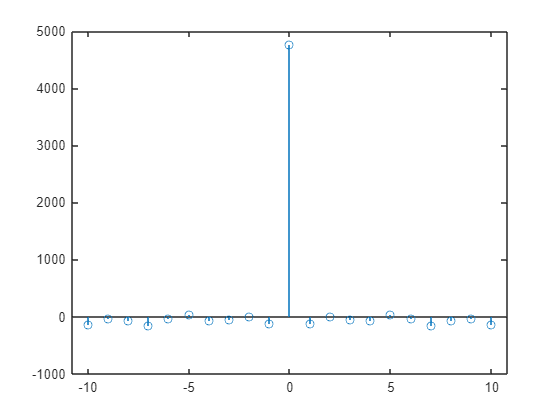

[tc, lagt] = xcorr(tst, 10);
stem(lagt, tc);

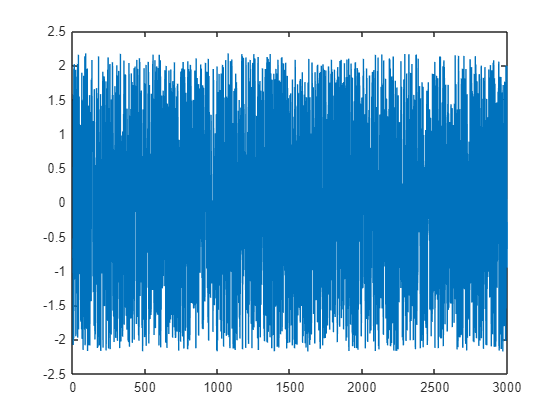

plot(tst);

max(tst)

ans = 2.1761

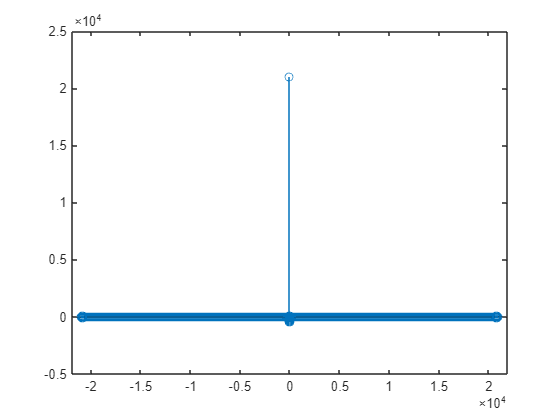

% Check correlation of Schroeder phase signal
[tusp, lagusp] = xcorr(usp);
figure;
stem(lagusp, tusp)

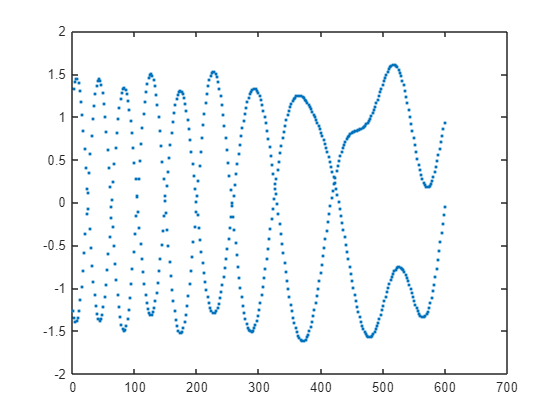

figure;
plot(usp(end-600:end), '.');